# **Fitting the MATLAB Logo Using Neural Networks**

### 1. Data Importation

**Format Requirement :**

To represent the computation of neural networks using linear algebra notation, the data should be in the form of a column vector, and the corresponding label should also be a column vector. For example: $f\left(x_1 ,x_2 \right)=x_1^2 +x_2^2$

                                                                 
$$\begin{array}{l}
{\mathit{\mathbf{d}}}_1 =\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack ,{\mathit{\mathbf{d}}}_2 =\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack \;,\;\ldotp \ldotp \ldotp \;,{\mathit{\mathbf{d}}}_N =\left\lbrack \begin{array}{c}
x_{1N} \\
x_{2N} 
\end{array}\right\rbrack \\
y_1 =\;\;2\;\;\;,{\;y}_2 =\;\;5\;\;\;,\;\ldotp \ldotp \ldotp \;\;,y_N \;=x_{1N}^2 +x_{2N}^{2\;} 
\end{array}$$


The data set for neural networks should consist of two matrices:  

    Data matrix : $\mathit{\mathbf{D}}\in R^{n_D \times N}$, where $n_D$ is the dimension of data and $N$ is the numbers of data.

    Label matrix : $\mathit{\mathbf{Y}}\in R^{n_L \times N}$, where $n_L$ is the dimension of label.

                                                                
$$\mathit{\mathbf{D}}=\left\lbrack \begin{array}{cccc}
1 & 1 & \ldotp \ldotp \ldotp  & x_{1N} \\
1 & 2 & \ldotp \ldotp \ldotp  & x_{2N} 
\end{array}\right\rbrack ,\;\;\mathit{\mathbf{Y}}=\left\lbrack \begin{array}{cccc}
1 & 5 & \ldotp \ldotp \ldotp  & x_{1N}^2 +x_{2N}^{2\;} 
\end{array}\right\rbrack$$


clear; clc; close all;
n=15;
x=1:2*n+1; y=1:2*n+1;
[X,Y]=meshgrid(x,y);
V=membrane(1,n);
Predictor=[X(:),Y(:)]';
Response=V(:)';

Data=Predictor;
Label=Response;

### 2. Data Visualization

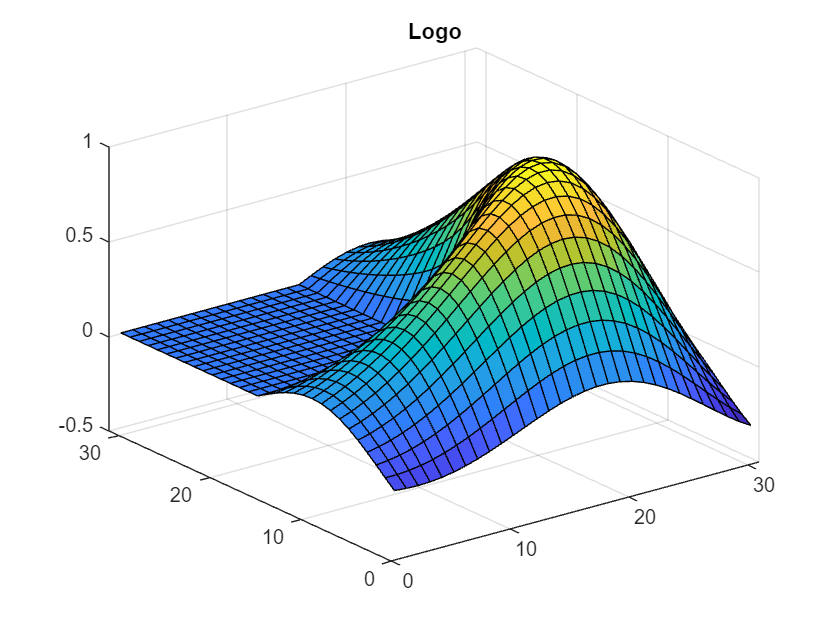

GridNumber=numel(x);
figure
surf(X,Y,reshape(Label,GridNumber,GridNumber))
title('Logo')

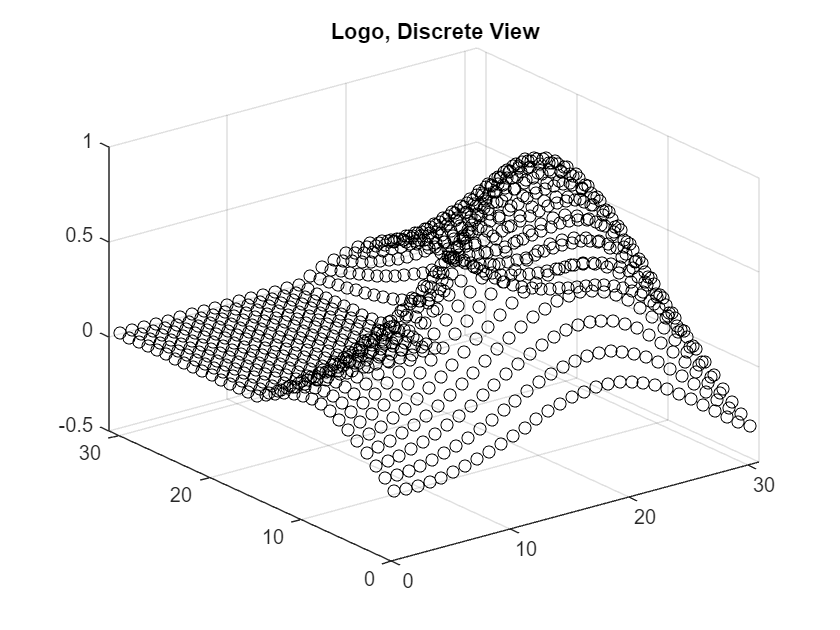

figure
scatter3(Data(1,:),Data(2,:),Label,'black')
title('Logo, Discrete View')

Our goal is to find a surface that represents the input-output relation between the data and label.

### 3. Specify The Structure & Type of Neural Networks

The package support two types of Neural Nets for function approximation & data fitting,

the first is Multilayer Perceptron (MLP) , the second is Residual Neural Networks (ResNet);

ResNet allow user to train deeper neural net without gradient vanishing problems.

To specify the type of network, use the command: NN.NetworkType='ANN' or 'ResNet', in this

example, we will use MLP to fit the logo.

close all
NN.NetworkType='ANN'; % MLP

The logo of MATLAB is the solution to the wave equation in a 2D plate,

i.e.$\;f\left(\mathit{\mathbf{x}}\right):R^2 \to R$ , so the input dimension of the MLP should be 2, and the output dimension is 1.

Define the network structure using following command:

the number between Input & OutputDimension are the size of hidden layers.

InputDimension=2; OutputDimension=1;
LayerStruct=[InputDimension,5,6,6,OutputDimension];

Specify the cost function to minimize using NN.Cost. Currently, the package provides two cost functions: the sum of square error (SSE) and the mean square error (MSE).

NN.Cost='SSE'; 

Specify the nonlinear activation function for NN using NN.ActivationFunction.

The built-in activation functions are: 1.'Gaussian' 2. 'Sigmoid' 3,'tanh'.

For function approximation, the recommand activation is 'gaussian'.

NN.ActivationFunction='Gaussian';

The data type of 'NN.ActivationFunction' can either be string or function handle, you can 

specify the activation function using function handle.

NN.ActivationFunction=@(x) exp(-x.^2);

The activation should be smooth for function approximation problems, so those commonly used activation for classification problems like 'ReLU' are not recommand.

Finally, use the command 'Initializeation' to Initialize the weights & biases of NN.

NN=Initialization(NN,LayerStruct);

'Initialization' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\Roy\Desktop\Modeling\OnlineSolver
    C:\Users\Roy\Desktop\Modeling\NeuralNetwork\OptimizationSolver\OnlineSolver
    C:\Users\Roy\Desktop\Modeling\NeuralNetwork\OptimizationSolver

Change the MATLAB current folder or add its folder to the MATLAB path.

### 4.Solve Least Square Problem By Numerical Optimization

The standard workflow for minimizing the cost function can be separated into two stages. The first stage involves using stochastic gradient descent (SGD)-based methods to avoid getting trapped by local minima. For SGD-based algorithms, the following information is required:

#### 4.1 Stochastic Gradient Descent Based Method

option.Solver='ADAM';
option.BatchSize=200;
option.MaxIteration=200;
option.s0=15e-3; % Step Size

Start optimizing using Adaptive Momentum Estimation. (ADAM)

NN=OptimizationSolver(Data,Label,NN,option);

#### 4.2 Quasi-Newton's Method

The following information are required when using Quasi-Newton's methods.

If the infinity norm of the gradient is less than terminate condition, the optimization process will be stop.

option.Solver='BFGS';
option.MaxIteration=300;
option.TerminateCondition=1e-4;

Start optimizing using Broyden-Fletcher-Goldfarb-Shanno method (BFGS).

NN=OptimizationSolver(Data,Label,NN,option);

### 5. Quatify & Visualize Fitting Performance

Use NN.Evaluate to predict & analyzing fitting results. 

Quatify the fitting performance  by the error vector : $\mathit{\mathbf{E}}=\mathit{\mathbf{Y}}-\textrm{NN}\left(\mathit{\mathbf{D}}\right),\;\;\;\mathit{\mathbf{E}}\in \;R^{1\times N}$

Prediction=NN.Evaluate(Data);
Error=Label-Prediction;
figure
histogram(Error)
title('Error Distribution')

Visualize the optimized neural network

figure
scatter3(Data(1,:),Data(2,:),Label(1,:),'black') 
hold on
[X,Y]=meshgrid(x,y);
n1=numel(x); n2=numel(y);
surf(X,Y,reshape(Prediction(1,:),n1,n2))
title('Neural Network Fit')
legend('Data','Fitting')
legend("Position", [0.74834,0.86095,0.23184,0.12127])
FirstOrderOptimality=NN.FirstOrderOptimality

The first order optimality may indicate the fitting potential of neural net, if the first order optimality is still large after optimization, you may consider using the BFGS method for further optimization of the neural network.

option.Solver='BFGS';
option.MaxIteration=100;
NN=OptimizationSolver(Data,Label,NN,option);